# 第2章 离散时间信号和系统分析基础

## 2.6 离散时间傅里叶变换

### 2.6.1 定义

#### `Ch2_6_1`

`模拟信号`$x_a \left(t\right)=\sin \left(2\pi \ast f_1 \ast t\right)+\cos \left(2\pi \ast f_2 \ast t\right)$`，`$f_1 =1\textrm{Hz},\;f_2 =2\textrm{Hz}$`，以`$f_s =16\textrm{Hz}$`采样`16`点得到数字序列`$x\left(n\right)$`。`

`求数字序列的离散时间傅里叶变换，``并画出其幅度谱和相位谱``。`

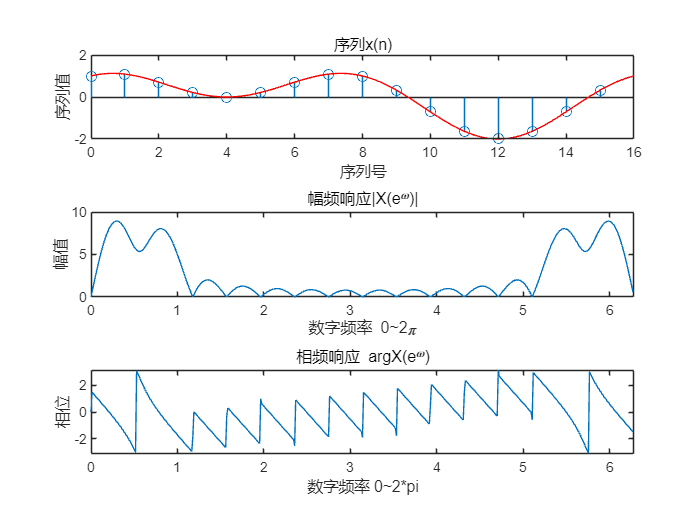

fs = 16;%Hz
f1 = 1; %Hz
f2 = 2; %Hz
N = 16;
n = 0:1:15;
dt = 0.001; %仿真步长：0.001s
t = 0:dt:1; %仿真时长：2s
xt = sin(2*pi*f1*t) + cos(2*pi*f2*t); 
%数字序列图
subplot(3,1,1);
x = sin(2*pi*(f1/fs)*n)+cos(4*pi*(f1/fs)*n);
stem(n,x);
xlim([0 16]);
ylim([-2 2]);
xlabel('序列号');
ylabel('序列值');
title('序列x(n)')
%增加轮廓线，便于观察；采样频率10Hz，采样间隔0.1s
hold on;
plot(t*16,xt,'red');
%序列DTFT图
K=512;
dw=2*pi/K;
k=0:511;
X=x*exp(-1i*dw*n'*k);
subplot(3,1,2); plot(k*dw,abs(X));
xlim([0 2*pi]); ylim([0 10]);
xlabel('数字频率 0~2\pi'); ylabel('幅值');
title('幅频响应|X(e^j^\omega)|');
subplot(3,1,3); plot(k*dw,angle(X));
xlim([0 2*pi]); ylim([-pi pi]);
xlabel('数字频率 0~2*pi'); ylabel('相位');
title('相频响应 arg{X(e^j^\omega)}')